# FF_VFI_AZ_LOOP Dynamic Savings Problem Loop Common Grid

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**Dynamic Asset**](https://fanwangecon.github.io/CodeDynaAsset/)** Repositories**

This is the example vignette for function: [**ff_vfi_az_loop**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_loop.m) from the [**MEconTools Package**](https://fanwangecon.github.io/MEconTools/)**. **This function solves the dynamic programming problem for a (a,z) model. Households can save a, and face AR(1) shock z. The problem is solved over the infinite horizon. This is the looped code, it is slow for larger state-space problems.  The code uses common grid, with the same state space and choice space grids.

**Links to Four Code:**

Four Core Savings/Borrowing Dynamic Programming Solution Functions that are functions in the [**MEconTools Package**](https://fanwangecon.github.io/MEconTools/)**. **:

- Common Choice and States Grid ***Loop***: [**ff_vfi_az_loop**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_loop.m), slow should use for testing new models

- Common Choice and States Grid ***Vectorized***:  [**ff_vfi_az_vec**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_vec.m), fast good for many purposes

- States Grid + Continuous Exact Savings as Share of Cash-on-Hand ***Loop***:[** ff_vfi_az_bisec_loop**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_bisec_loop.m), high precision even with small grid

- States Grid + Continuous Exact Savings as Share of Cash-on-Hand ***Vectorized***: [**ff_vfi_az_bisec_vec**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_bisec_vec.m), precision and speed

The four sample codes are written for the standard dynamic savings problem with AR(1) shock that is one of the core problems introduced in first sessions of graduate Economics courses. The code can be easily adapted to accomand multiple assets, savings and borrowing, discrete and continuous choice, etc. A large proportion of dynamic economic models are based on the underlying structure of solving a model with endogenous states and exogenous shocks, and that is what the (a,z) model does. In general, one should write looped code first to make sure the economics is correct, then vectorized code can be adopted to increase speed. 

## Test FF_VFI_AZ_LOOP Defaults

Call the function with defaults. By default, shows the asset policy function summary. Model parameters can be changed by the mp_params.

%mp_params
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('fl_crra') = 1.5;
mp_params('fl_beta') = 0.94;
% call function
ff_vfi_az_loop(mp_params);

Elapsed time is 1.291175 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
          i    idx    ndim    numel    rowN    colN     sum      mean      std     coefvari    min    max
          _    ___    ____    _____    ____    ____    _____    ______    _____    ________    ___    ___

    ap    1     1      2       700     100      7      16864    24.091    14.08    0.58446      0     50 

xxx TABLE:ap xxxxxxxxxxxxxxxxxx
              

## Test FF_VFI_AZ_LOOP Speed Tests

Call the function with different a and z grid size, print out speed:

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_timer') = true;
mp_support('ls_ffcmd') = {};

A grid 50, shock grid 5:

mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 50;
mp_params('it_z_n') = 5;
ff_vfi_az_loop(mp_params, mp_support);

Elapsed time is 0.223217 seconds.


A grid 100, shock grid 7:

mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 100;
mp_params('it_z_n') = 7;
ff_vfi_az_loop(mp_params, mp_support);

Elapsed time is 1.284511 seconds.


A grid 200, shock grid 9:

mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 200;
mp_params('it_z_n') = 9;
ff_vfi_az_loop(mp_params, mp_support);

Elapsed time is 6.325330 seconds.


## Test FF_VFI_AZ_LOOP Control Outputs

Run the function first without any outputs;

mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 50;
mp_params('it_z_n') = 5;
mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_timer') = false;
mp_support('bl_print_params') = false;
mp_support('bl_print_iterinfo') = false;

Run the function and show policy function for savings choice. For ls_ffcmd, ls_ffsna, ls_ffgrh, can include these: 'v', 'ap', 'c', 'y', 'coh', 'savefraccoh'. These are value, aprime savings choice, consumption, income, cash on hand, and savings fraction as cash-on-hand.

Elapsed time is 0.313830 seconds.
xxx  ff_vfi_az_vec, outcome=ap  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group      a       mean_z_0_54195    mean_z_0_66401    mean_z_0_88162    mean_z_1_3095    mean_z_2_2745
    _____    ______    ______________    ______________    ______________    _____________    _____________

      1           0             0                 0                 0                0           1.0204    
      2      1.0204             0                 0            1.0204           1.0204           2.0408    
      3      2.0408        1.0204            1.0204            2.0408           2.0408           3.0612    
      4      3.0612        2.0408            2.0408            2.0408           3.0612           4.0816    
      5      4.0816

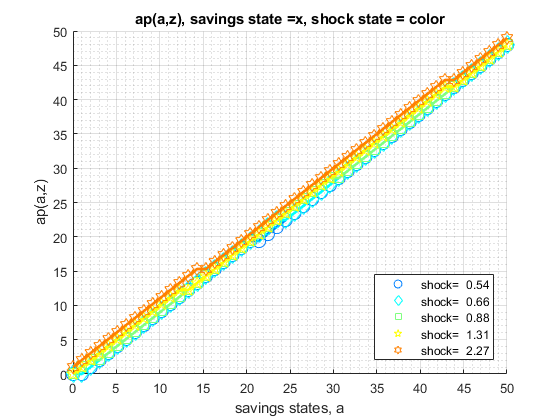

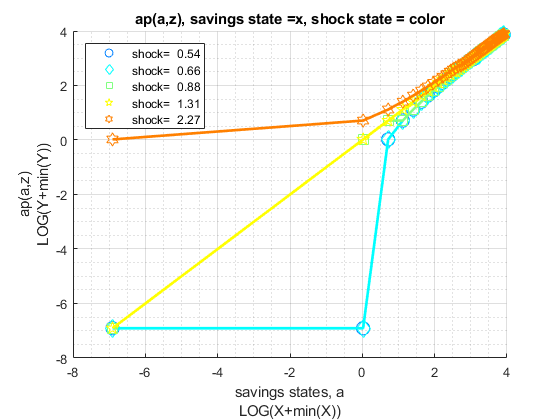

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_print_params') = false;
mp_support('bl_print_iterinfo') = false;
% ls_ffcmd: summary print which outcomes
mp_support('ls_ffcmd') = {};
% ls_ffsna: detail print which outcomes
mp_support('ls_ffsna') = {'ap'};
% ls_ffgrh: graphical print which outcomes
mp_support('ls_ffgrh') = {'ap'};
ff_vfi_az_loop(mp_params, mp_support);

Run the function and show summaries for savings and fraction of coh saved:

mp_params('it_a_n') = 100;
mp_params('it_z_n') = 9;
mp_support('ls_ffcmd') = {'ap', 'savefraccoh'};
mp_support('ls_ffsna') = {};
mp_support('ls_ffgrh') = {};
mp_support('bl_vfi_store_all') = true; % store c(a,z), y(a,z)
ff_vfi_az_loop(mp_params, mp_support);

Elapsed time is 1.867278 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean        std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    ______    _______    _______    ________    ___    _______

    ap             1     1      2       900     100      9       21825      24.25     14.089      0.581      0          50
 

## Test FF_VFI_AZ_LOOP Change Interest Rate and Discount

Show only save fraction of cash on hand:

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_print_params') = false;
mp_support('bl_print_iterinfo') = false;
mp_support('ls_ffcmd') = {'savefraccoh'};
mp_support('ls_ffsna') = {};
mp_support('ls_ffgrh') = {};
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 50;
mp_params('it_z_n') = 5;
mp_params('fl_a_max') = 50;
mp_params('st_grid_type') = 'grid_powerspace';

Solve the model with several different interest rates and discount factor:

% Lower Savings Incentives
mp_params('fl_beta') = 0.80;
mp_params('fl_r') = 0.01;
ff_vfi_az_loop(mp_params, mp_support);

Elapsed time is 0.113265 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean       std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    ______    _______    ______    ________    ___    _______

    savefraccoh    1     1      2       250      50      5      118.68    0.47472    0.2843    0.59887      0     0.80805

xxx

% Higher Savings Incentives
mp_params('fl_beta') = 0.95;
mp_params('fl_r') = 0.04;
ff_vfi_az_loop(mp_params, mp_support);

Elapsed time is 0.327279 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean        std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    ______    _______    _______    ________    ___    _______

    savefraccoh    1     1      2       250      50      5      160.99    0.64394    0.29947    0.46506      0     0.94888



## Test FF_VFI_AZ_LOOP Changing Risk Aversion

Here, again, show fraction of coh saved in summary tabular form, but also show it graphically.

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_print_params') = false;
mp_support('bl_print_iterinfo') = false;
mp_support('ls_ffcmd') = {'savefraccoh'};
mp_support('ls_ffsna') = {};
mp_support('ls_ffgrh') = {'savefraccoh'};
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 100;
mp_params('it_z_n') = 5;
mp_params('fl_a_max') = 50;
mp_params('st_grid_type') = 'grid_powerspace';

Solve the model with different risk aversion levels, higher preferences for risk:

Elapsed time is 0.581794 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean        std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    ______    _______    _______    ________    ___    _______

    savefraccoh    1     1      2       500     100      5      268.82    0.53764    0.29852    0.55524      0     0.86141



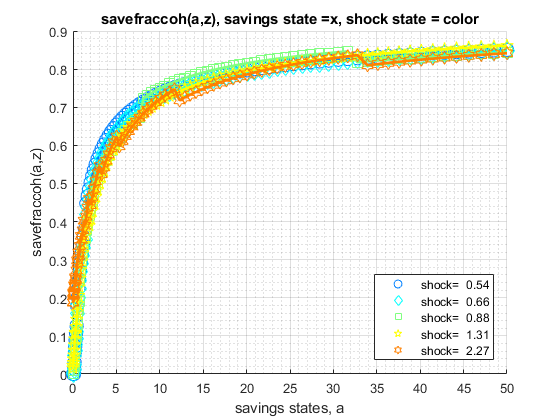

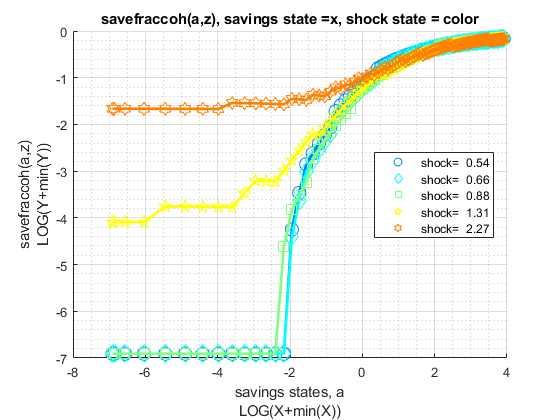

% Lower Risk Aversion
mp_params('fl_crra') = 0.5;
ff_vfi_az_loop(mp_params, mp_support);

When risk aversion increases, at every state-space point, the household wants to save more.

Elapsed time is 0.937495 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean        std      coefvari    min     max  
                   _    ___    ____    _____    ____    ____    ______    _______    _______    ________    ___    ______

    savefraccoh    1     1      2       500     100      5      335.64    0.67129    0.28688    0.42735      0     0.9488

xxx

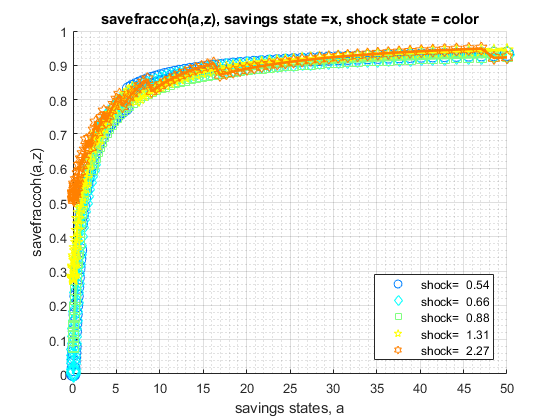

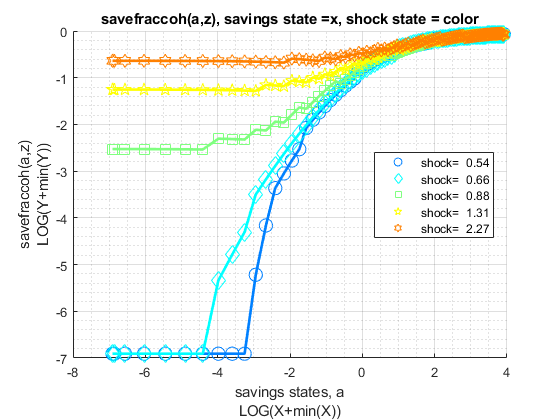

% Higher Risk Aversion
mp_params('fl_crra') = 5;
ff_vfi_az_loop(mp_params, mp_support);

## Test FF_VFI_AZ_LOOP with Higher Uncertainty

Increase the standard deviation of the Shock. 

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_print_params') = false;
mp_support('bl_print_iterinfo') = false;
mp_support('ls_ffcmd') = {'savefraccoh'};
mp_support('ls_ffsna') = {};
mp_support('ls_ffgrh') = {};
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 100;
mp_params('it_z_n') = 5;
mp_params('fl_a_max') = 50;
mp_params('st_grid_type') = 'grid_powerspace';

Lower standard deviation of shock:

% Lower Risk Aversion
mp_params('fl_shk_std') = 0.10;
ff_vfi_az_loop(mp_params, mp_support);

Elapsed time is 0.957457 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum      mean       std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    _____    ______    _______    ________    ___    _______

    savefraccoh    1     1      2       500     100      5      294.1    0.5882    0.32083    0.54544      0     0.92392

xxx TA

Higher shock standard deviation: low shock high asset save more, high shock more asset save less, high shock low asset save more:

% Higher Risk Aversion
mp_params('fl_shk_std') = 0.40;
ff_vfi_az_loop(mp_params, mp_support);

Elapsed time is 0.923630 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean        std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    ______    _______    _______    ________    ___    _______

    savefraccoh    1     1      2       500     100      5      350.37    0.70073    0.26741    0.38162      0     0.93257

